Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Assignment 9c -- Engine Data

%{
    This will be a script that will be used to complete Assignment 9c 
    for ME 5714 -- Digital Signal Processing.

    Sam Kramer
    April 3rd, 2023
%}

% --Setup
clear; clc; close all; format compact;

Assignment 9c

turbine analysis continued

Following the assignment 9, in this assignment we’ll estimate the transfer function between the pressure transducer and the microphone data.

- Select 1 independent vector of the input, pressure sensor data, make the vector length 8192 samples. 

- Design a bandpass filter, Butterworth, with a center frequency equivalent to the blade pass frequency and the upper and lower cutoff at 10% above the center frequency and 10% below the center frequency. Use a 4th order filter. Filter the vector Plot

- Re filter the data vector using the filtfilt function. Take the difference between the filtfilt result and the original vector. Discuss the result

## Part 1: Making a vector of 8192 samples of data

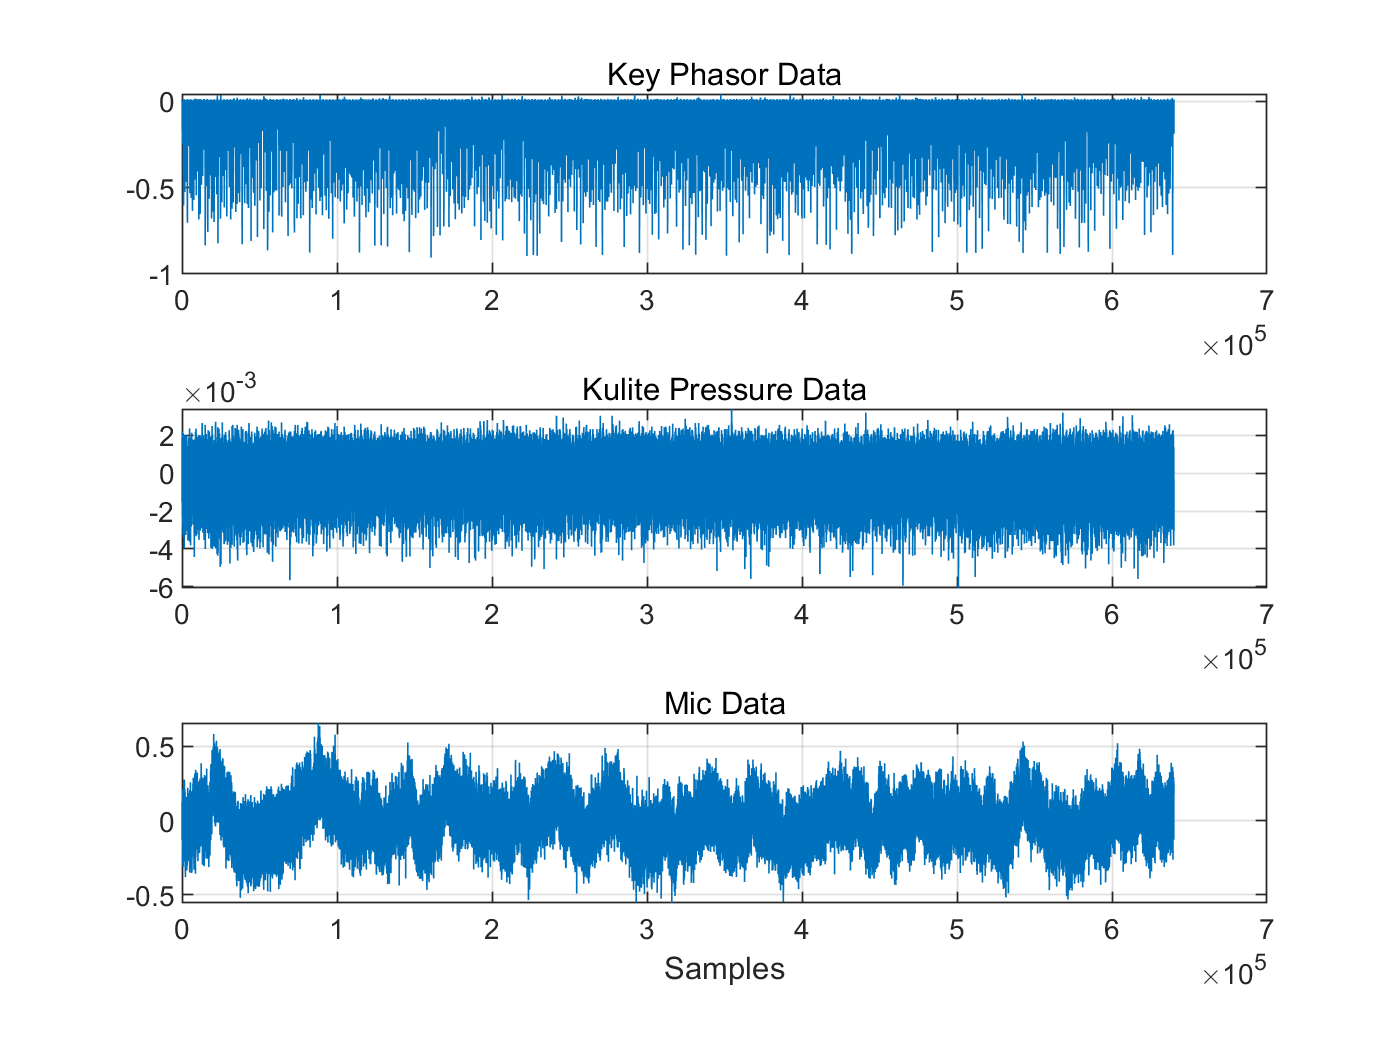

% --Load in data
    data = load('turbine data-1.mat');
    key_phasor = data.keyphasor;
    kulite_pressure = data.kulitepressure;
    mic_data = data.mic;
    
% --Zero Mean Data
    key_phasor = key_phasor - mean(key_phasor);
    kulite_pressure = kulite_pressure - mean(kulite_pressure);
    mic_data = mic_data - mean(mic_data);
    
% --Plot Data
    figure(1)
    subplot(3,1,1)
    plot(key_phasor)
        hold on
        grid on
        subtitle('Key Phasor Data')
    
    subplot(3,1,2)
    plot(kulite_pressure)
        grid on
        subtitle('Kulite Pressure Data')
    
    subplot(3,1,3)
    plot(mic_data)
        grid on

        subtitle('Mic Data')
        xlabel('Samples')
        
% --Putting pressure into data vectors
    vector_numbers = 1;
    kulite_ensemble = [];
    data_points = 8192;         % Target Number of data points
    sample_freq = 128000;       % Sample Frequency (samples/sec)
    
    for N = 1:vector_numbers
        
        kulite_ensemble = [kulite_ensemble, kulite_pressure(N*data_points:(N+1)*data_points - 1, 1)];
        
    end

## Part 2: Designing a Bandpass Butterworth Filter

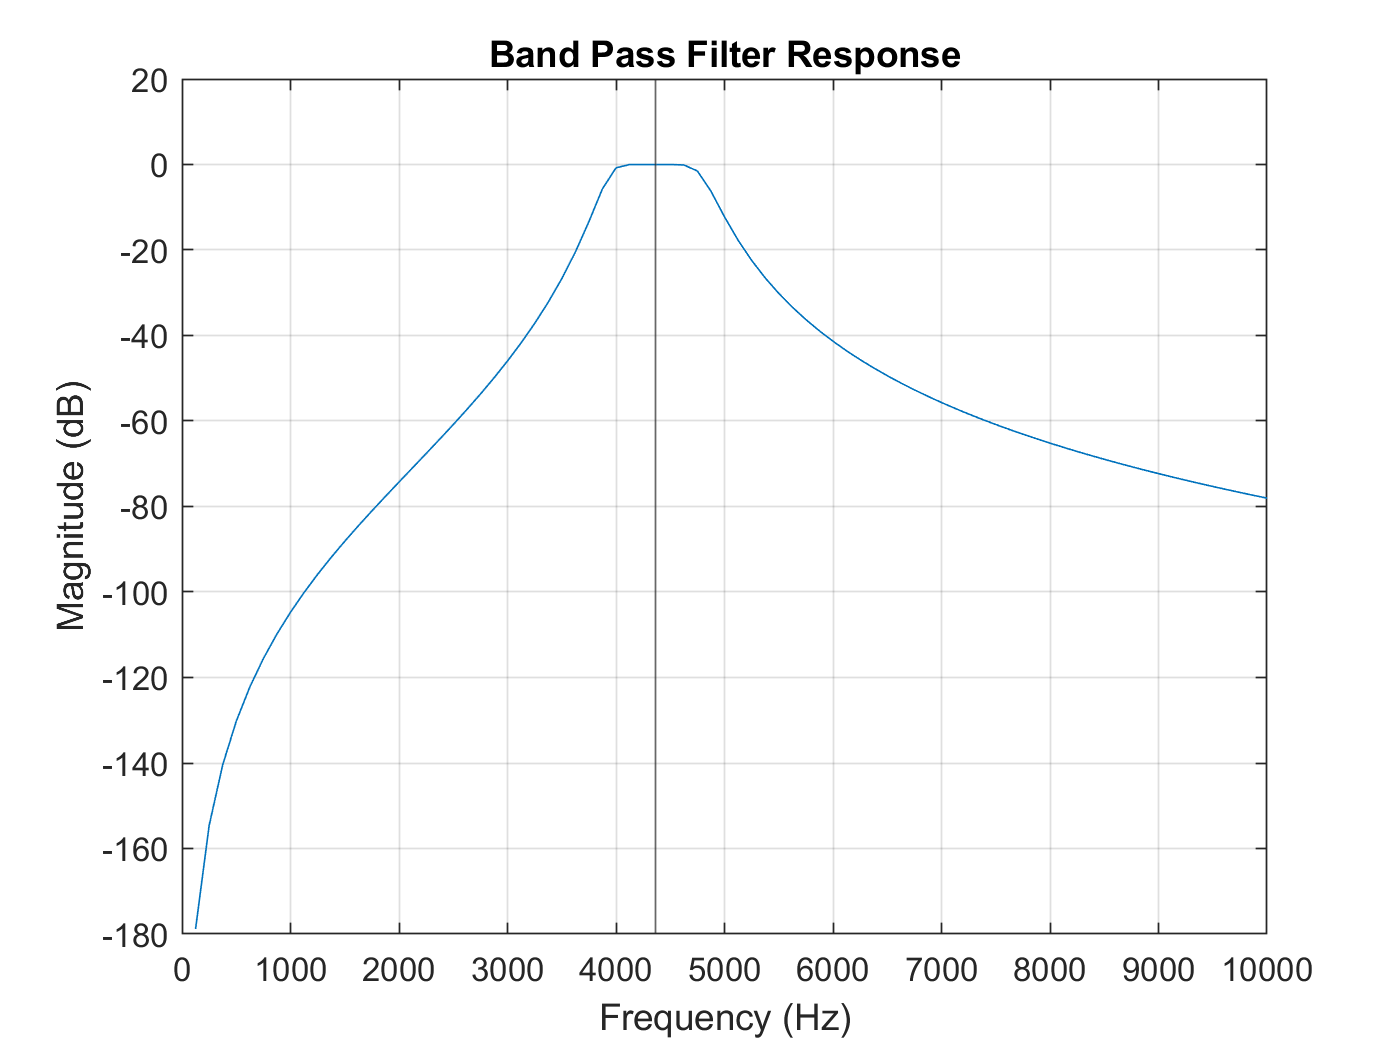

% --Filter parameters
    order = 4;                                                          % Order of filter
    nyquist = sample_freq / 2;                                          % Nyquist frequency of filter
    fc = 4363;                                                          % Bandpass center
    wn = [(fc - .1*fc), (fc + 0.1*fc)];
    wn = wn./nyquist;   
    
% --Using butterworth filter 
   [b,a] = butter(order, wn);   
   
% --Outputting the frequency response
    [h,w] = freqz(b,a,[],sample_freq);
    
    figure(2)
    plot(w, 20*log10(abs(h)))
        hold on
        grid on
        xlim([0 10000])
        xline(fc)
        title('Band Pass Filter Response')
        xlabel('Frequency (Hz)')
        ylabel('Magnitude (dB)')

## Part 3: Filtering Data using Filter() Function

% --Using the filter function
    filt_kulite = filter(b,a,kulite_ensemble);

## Part 4: Filtering Data Using filtfilt() Function

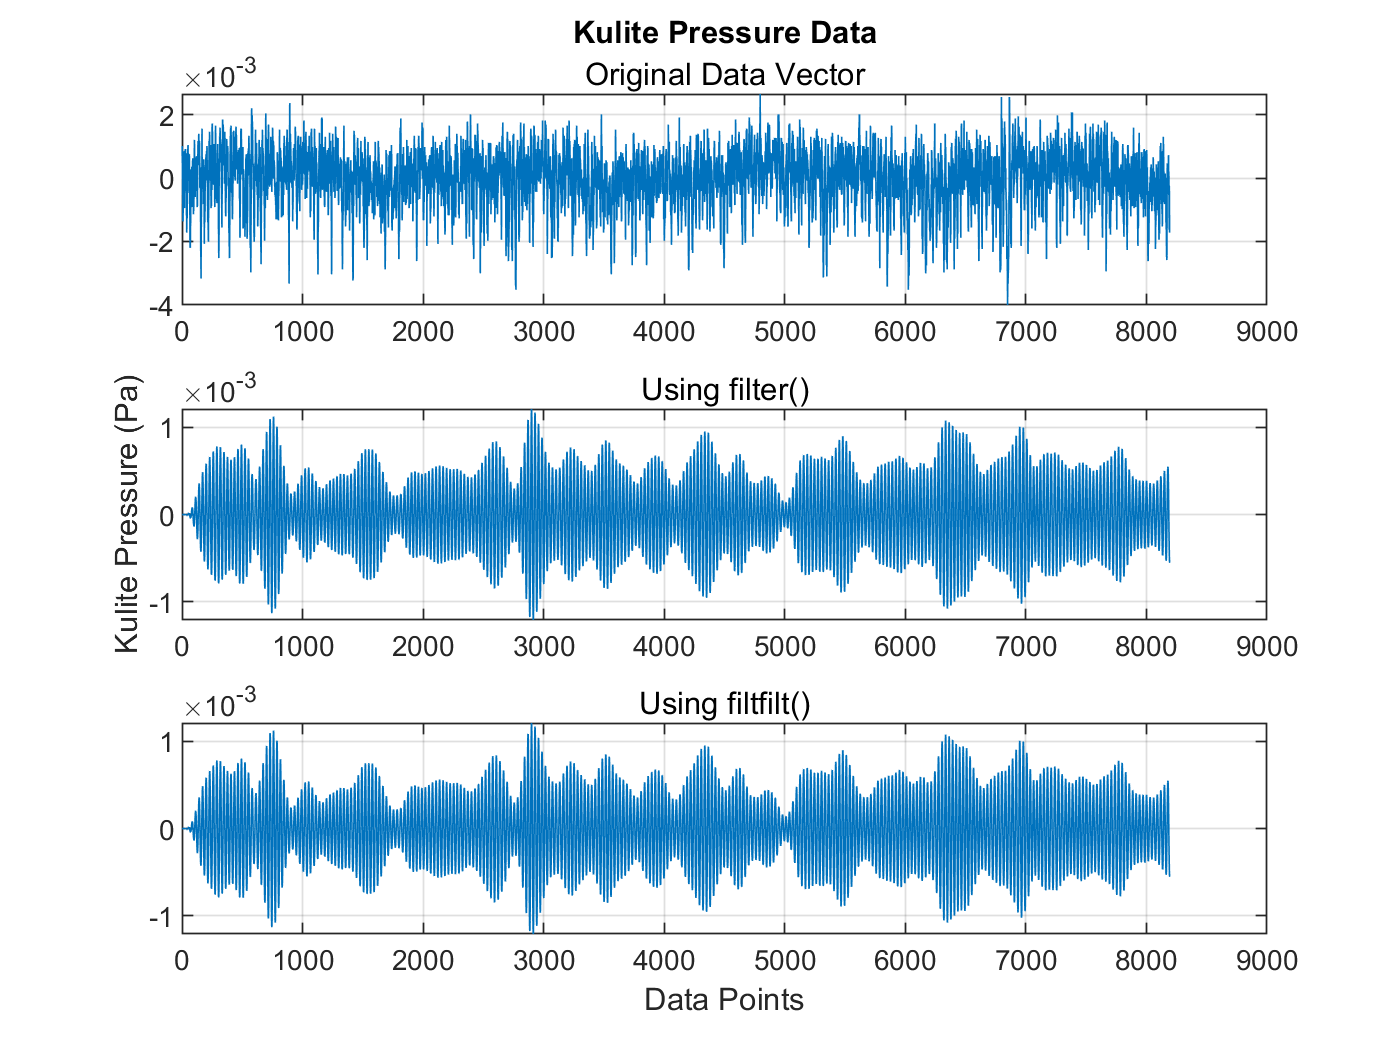

% --Using the filtfilt function
    filtfilt_kulite = filter(b,a,kulite_ensemble);
    
% --Plotting the filtered data
    figure(3)
    subplot(3,1,1)
    plot(kulite_ensemble)
        title('Kulite Pressure Data')
        subtitle('Original Data Vector')
        grid on
    
    subplot(3,1,2)
    plot(filt_kulite)
        ylabel('Kulite Pressure (Pa)')
        subtitle('Using filter()')
        grid on
        
    subplot(3,1,3)
    plot(filtfilt_kulite)
        xlabel('Data Points')
        subtitle('Using filtfilt()')
        grid on

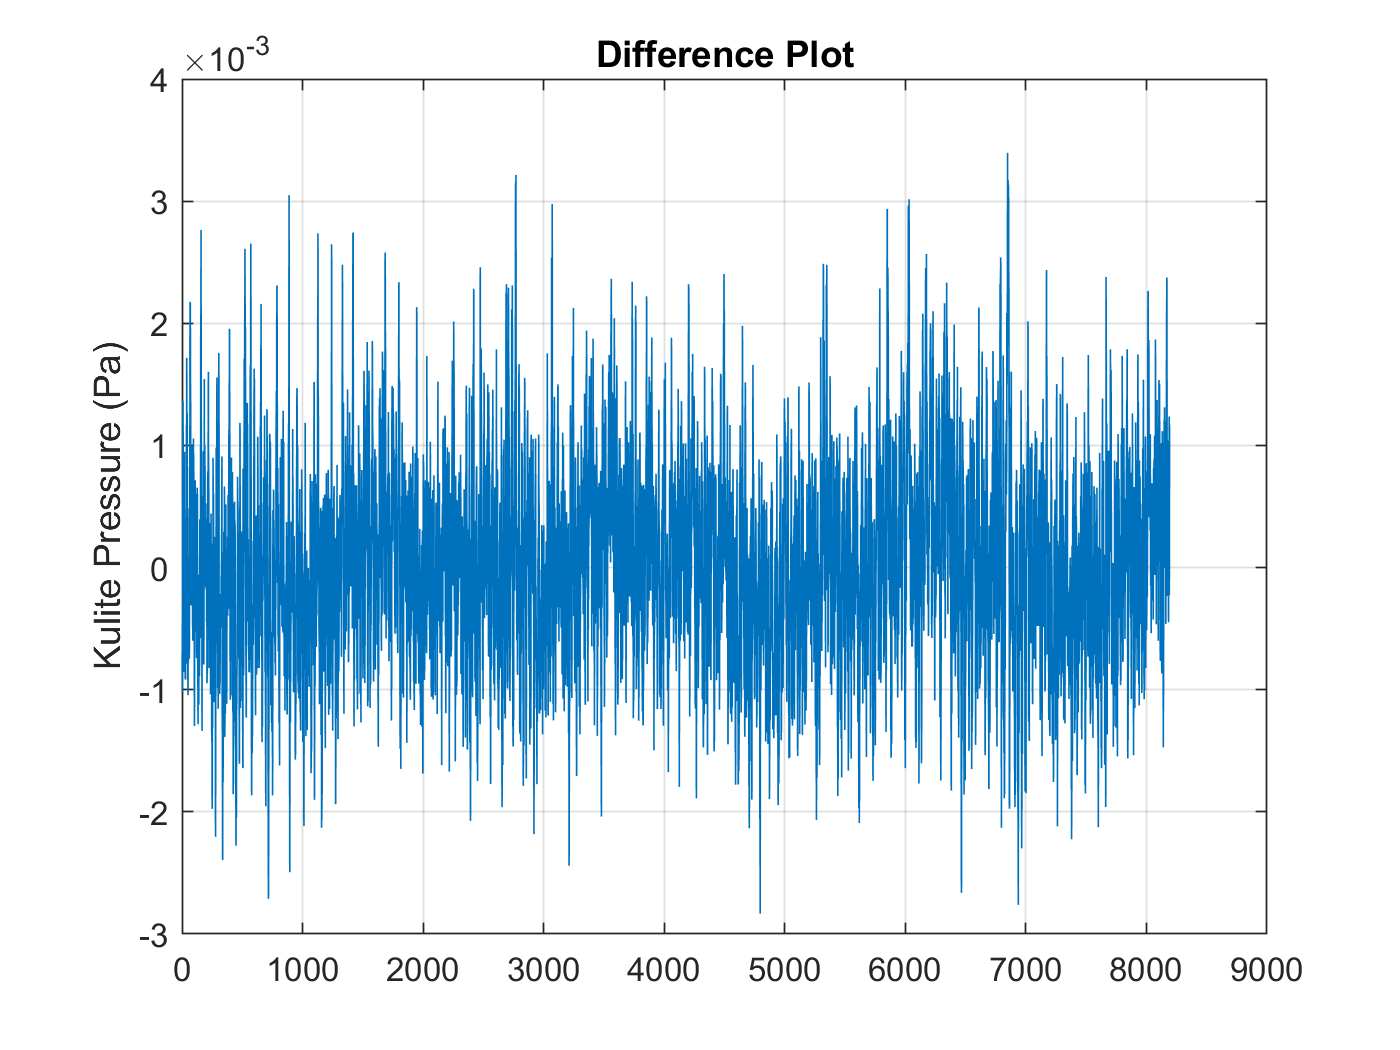

        
% --Taking difference in data
    pressure_difference = filtfilt_kulite - kulite_ensemble;
    
% --Plot difference in data
    figure(4)
    plot(pressure_difference)
        hold on
        grid on
        title('Difference Plot')
        ylabel('Kulite Pressure (Pa)')   

    Based on the difference plot, the magnitude of the peaks increases, however this is because there are negative values in the filtered data, and so subtracting the filtered data would increase the magnitude. However the data is centered around zero, which could seem to point to the data being random additive noise.